# **Analysis of the snake path**

## Plotting the path of the different body parts

- data(:,1) : x values

- data(:,2) : y values

- date(:,3) : azimuth (modulo [-$\pi$;$\pi$] )

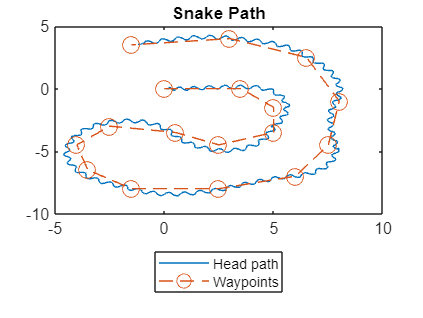

plot(out.body_1.Data(:,1),out.body_1.Data(:,2))
hold on

plot(out.des_waypoint.Data(:,1),out.des_waypoint.Data(:,2),"--o","MarkerSize",10)
hold off
title("Snake Path")
legend("Head path","Waypoints",Location="southoutside")

## Plotting the heading direction of the snake

The azimuth is computed as the mean of all the directions taken by the head within each oscillation period.

This method is easy to compute in simulink and gives good results.

The frequency of the oscillation is 2.5 rad/sec $ = 2.5/2\pi = 1.25/\pi = 0.397887 Hz$

==> See the Simulink model for computation

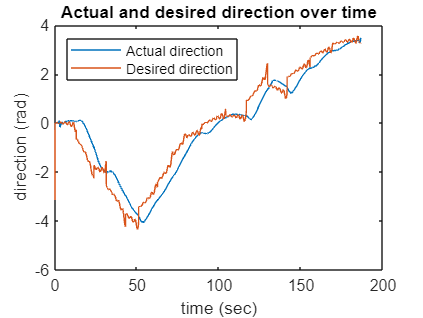

figure
plot(out.head_dir.Time,out.head_dir.Data)
hold on
plot(out.des_head.Time,out.des_head.Data)
hold off
title("Actual and desired direction over time")
xlabel("time (sec)")
ylabel("direction (rad)")
legend("Actual direction","Desired direction",Location="northwest")

Plotting the error angle and comparing the non unwraped angle with the unwraped angle

figure
%plot(out.non_unwrap.Time,out.non_unwrap.Data)
hold on
plot(out.angle_unwrap.Time,out.angle_unwrap.Data)
hold off
legend("non unwrap","unwrap")

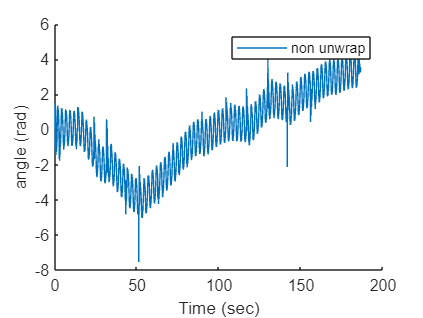

xlabel("Time (sec)")
ylabel("angle (rad)")